# SAMEKO - LCC for switches and crossings

WP with Kristofer & Arne

## Input

% set parameters
time_horizon_switches = 45; % time horizon in years
time_horizon_components = 10;
% read regression results
[prev,korr,renewal,headers] = read_input_data();
switches = 1:15;
components = 16:23;

## LCC & annuity

### > Switches

% Annuity for different lifetimes
headers_switches = headers(1,switches);
renewal_costs_switches = renewal(switches,1);
annuity_switches = zeros(time_horizon_switches,size(headers_switches,2));
for y=1:time_horizon_switches
    [~, annuity_switches(y,:)] = assess_lcc(prev,korr,y,renewal_costs_switches,headers_switches);
end
% Find the optimal lifetime (where annuity is minimal)
[min_annuity_switches, optimal_lifetime_switches] = min(annuity_switches,[], 1);

### > Components

% Annuity for different lifetimes
headers_components = headers(1,components);
renewal_costs_components = renewal(components,1);
annuity_components = zeros(time_horizon_components,size(headers_components,2));
for y=1:time_horizon_components
    [~, annuity_components(y,:)] = assess_lcc(prev,korr,y,renewal_costs_components,headers_components);
end
% Find the optimal lifetime (where annuity is minimal)
[min_annuity_components, optimal_lifetime_components] = min(annuity_components,[], 1);

## Plots

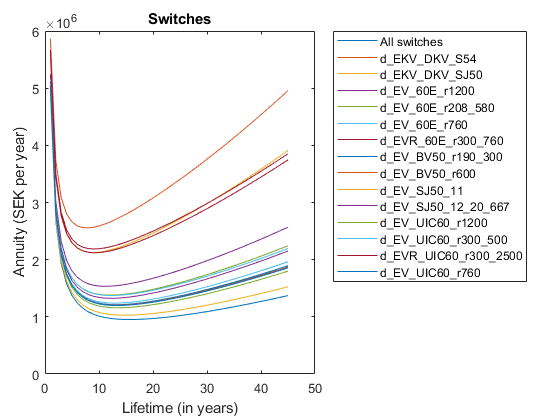

% Annuity for switches
plot(1:time_horizon_switches, annuity_switches)
legend(headers_switches, "Location","bestoutside")
xlabel("Lifetime (in years)")
ylabel("Annuity (SEK per year)")
title('Switches')

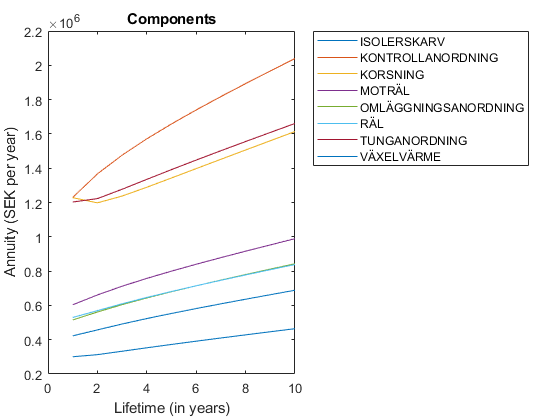


% Annuity for components
plot(1:time_horizon_components, annuity_components)
legend(headers_components, "Location","bestoutside")
xlabel("Lifetime (in years)")
ylabel("Annuity (SEK per year)")
title('Components')

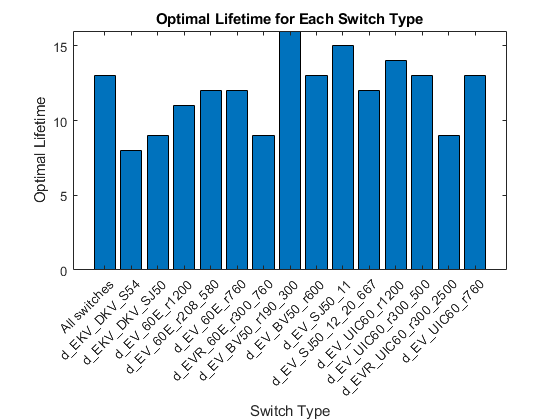


% lifetime for switches
figure;
bar(optimal_lifetime_switches);
xlabel('Switch Type');
ylabel('Optimal Lifetime');
title('Optimal Lifetime for Each Switch Type');
set(gca, 'XTick', 1:length(switches), 'XTickLabel', headers_switches);

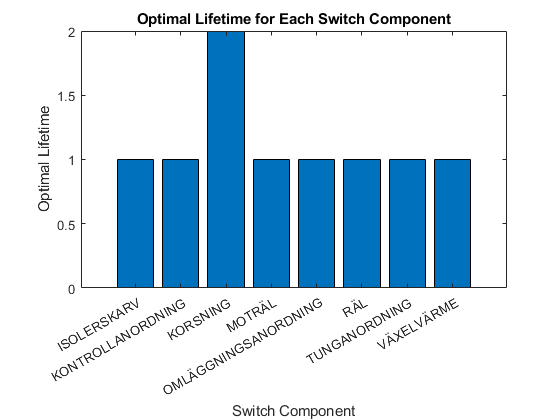


% lifetime for components
figure;
bar(optimal_lifetime_components);
xlabel('Switch Component');
ylabel('Optimal Lifetime');
title('Optimal Lifetime for Each Switch Component');
set(gca, 'XTick', 1:length(components), 'XTickLabel', headers_components);